# create Y_G for different noises., Spherical formfactor

dnames = {'normal','lognormal','schulz','exponential', ...
    'boltzmann','triangular','uniform'};
PSFset=[[3 3];[3 15];[3 25];[25 25];[45 25]];
ndiv=2;
if 1
    % diamond
    SD_dist=360;
    det_side=7/ndiv;
    DETpix=round(1000/ndiv);
    lambda=0.1;
    PSF0=bartlett2d(3,15);
else
    % lab saxs
    SD_dist=150;
    det_side=7/ndiv;
    DETpix=round(1000/ndiv);
    lambda=0.15;
    PSF0=bartlett2d(25,25);
end
rg=4;
use_r3=0;
use_g3=0;

Pxn=[87 85 135 133];
% Pxn=[83 91 103 113]; Pxn=[11 17 3 5];
V_power=.5;
dist_type=dnames{2}; dist_param.N=41;
Vlist=(linspace(0.004^(V_power),0.3^(V_power),100)+0.0000).^(1/V_power);%
% nulist=-0.016;%-1/63;%(-0.016);
nulist=-1/63;%(-0.016);
P_i=2;
PSF0=bartlett2d(PSFset(P_i,1),PSFset(P_i,2));

Dlog=[];
for j=1:numel(nulist)


    %     NNOIS=0;
    for NNOIS=[ -1/1.6749*10.^([linspace(3,5,5) ]) 0]
        for dist_i=[2]
            for i=1:numel(Vlist)
                if NNOIS
                    [q_mat_x,q_mat_y,I_mat,distrp] = Scatter2D(rg, NNOIS, Vlist(i), nulist(j), DETpix, SD_dist, lambda, det_side, PSF0,dnames{dist_i},dist_param,6);
                else
                    [q_mat_x,q_mat_y,I_mat,distrp] = Scatter2D(rg, NNOIS, Vlist(i), nulist(j), DETpix, SD_dist, lambda, det_side, 1,dnames{dist_i},dist_param,6);
                end                    
                % Compute q-spacing (assume roughly uniform on q_mat_y)
                qvr=hypot(q_mat_y,q_mat_x);
                uqy = unique(q_mat_y(:));
                if numel(uqy) < 2
                    error('q_mat_y grid is degenerate; need at least two unique samples.');
                end
                dq = mean(diff(uqy));
                RG2=rg^2;
                signum=4;

                [~, ~, ~,res] = MG_extract(Pxn, q_mat_x, q_mat_y, I_mat, signum,rg^2,use_r3,use_g3);
                if ~isreal(res.p)
                    disp(';')
                end
                p=res.p;
                g0=p(1);
                g1=p(2);
                g2=p(3);
                m1=p(use_g3+4);
                m2=p(use_g3+5);
                Dlog(end+1).Yg100=g1/g0/g0;
                Dlog(end).dist=dnames{dist_i};
                Dlog(end).nphot=-NNOIS/dq^2;
                Dlog(end).PSF0=PSFset(P_i,:);
                Dlog(end).PSF0c=PSFset(P_i,1)+1i*PSFset(P_i,2);
                Dlog(end).nu=nulist(j);
                Dlog(end).Yg210=g2/g1/g0;
                Dlog(end).Ym210=m2/m1/g0;
                Dlog(end).mean_r=sum(distrp.r.*distrp.p)/sum(distrp.p);
                Dlog(end).V=sum(distrp.r.^2.*distrp.p)/sum(distrp.p)./Dlog(end).mean_r.^2-1;
            end
        end
    end
end
Dlog=struct2table(Dlog);
% save Dlog_sphere_lognorm_r5_quad.mat dq PSF0 dist_param use_r3 use_g3
% Dlog rg Pxn save Dlog_sphere_lognorm_r4_quadMG0.79.mat dq PSF0 dist_param
% use_r3 use_g3 Dlog rg Pxn

## 1. Configuration & Reference Preparation

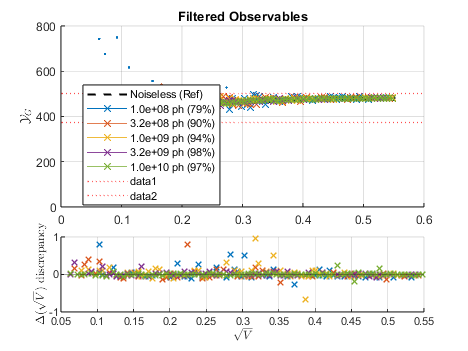

% load Dlog_sphere_lognorm_r4_quadMG0.79.mat

margin_pct = 0.20; % <--- ADJUSTABLE: Margin at the high-variance side
smooth_win = 3;    % Window for noiseless curve smoothing

% Helper to convert number to "3.2 * 10^{8}" LaTeX string
latex_noise = @(x) regexprep(sprintf('%0.1e', x), 'e[+]{0,1}(-?)0*(\d+)', '\\times 10^{$1$2}');

Dlog_orig = table2struct(Dlog);
noislist = unique([Dlog_orig.nphot]);
% noislist=noislist(noislist~=0);

% --- Extract Noiseless Reference ---
ref_idx = [Dlog_orig.nphot] == 0;
Dlog_ref = struct2table(Dlog_orig(ref_idx));


[ref_sqrtV, s_idx] = sort(sqrt(Dlog_ref.V));


ref_YG_raw = Dlog_ref.Yg100(s_idx);

% --- Smooth the Reference ---
kernel = ones(1, smooth_win) / smooth_win;
ref_YG_smooth = conv(ref_YG_raw, kernel, 'same');
ref_YG_smooth(1) = ref_YG_raw(1);     % Fix edges
ref_YG_smooth(end) = ref_YG_raw(end); 

% --- Determine Dynamic Range Limits ---
y_start = ref_YG_smooth(1);
y_end   = ref_YG_smooth(end);
y_span  = abs(y_end - y_start);

if y_end >= y_start
    y_limit_low  = min(ref_YG_smooth) - 0.05 * y_span; 
    y_limit_high = y_end + margin_pct * y_span;      
else
    y_limit_low  = y_end - margin_pct * y_span;      
    y_limit_high = max(ref_YG_smooth) + 0.05 * y_span;
end

% --- Setup Derivative & Interpolants ---
dYG_dsqrtV = gradient(ref_YG_smooth) ./ gradient(ref_sqrtV);
[YG_unique, u_idx] = unique(ref_YG_smooth);
deriv_unique = dYG_dsqrtV(u_idx);


% ref_YG_at_V: Ground truth lookup
ref_YG_at_V = @(v) interp1(ref_sqrtV, ref_YG_smooth, v, 'linear', 'extrap');
% ref_deriv_at_YG: Sensitivity lookup at measured point
ref_deriv_at_YG = @(yg) interp1(YG_unique, deriv_unique, yg, 'linear', 'extrap');

% 2. Main Plotting Loop (Observables & Discrepancy)
figure(6); clf;
violin_data = struct(); 
v_idx = 0; 
    colors = lines(numel(noislist)+1);

for nois_i = 1:numel(noislist)
    current_nphot = noislist(nois_i);
    Dlog_curr = struct2table(Dlog_orig);
    Dlog_curr = Dlog_curr(Dlog_curr.nphot == current_nphot & abs([Dlog_curr.mean_r] - rg) < 0.01, :);
    if isempty(Dlog_curr), continue; end
    
    [curr_sqrtV, s_idx] = sort(sqrt(Dlog_curr.V));
    curr_YG = Dlog_curr.Yg100(s_idx);
    
    % --- Determine Validity ---
    valid_mask = (curr_YG >= y_limit_low) & (curr_YG <= y_limit_high);
    percent_valid = (sum(valid_mask) / numel(valid_mask)) * 100;
    
    % --- Top Panel: Y_G Plotting ---
    subplot(3,1,[1 2]); hold on;
    if current_nphot == 0
        % Noiseless: Raw points + Smooth line
        plot(curr_sqrtV, curr_YG, 'ko', 'MarkerSize', 4, 'HandleVisibility', 'off');
        plot(curr_sqrtV, ref_YG_smooth, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Noiseless (Ref)');
    else
        % Noisy: Greyed out invalid, Solid valid
        if any(~valid_mask)
            plot(curr_sqrtV(~valid_mask), curr_YG(~valid_mask), '.', 'Color', colors(nois_i-1,:), 'HandleVisibility', 'off');
        end
        plot(curr_sqrtV(valid_mask), curr_YG(valid_mask), 'x-', 'LineWidth', 0.2,'Color',colors(nois_i-1,:), ...
            'DisplayName', sprintf('%0.1e ph (%d%%)', current_nphot, round(percent_valid)));
    end
    
    % --- Bottom Panel: Discrepancy (Calculated only for valid points) ---
    if any(valid_mask)
        v_idx = v_idx + 1;
        v_sqrtV = curr_sqrtV(valid_mask);
        v_YG = curr_YG(valid_mask);
        
        YG_truth = ref_YG_at_V(v_sqrtV);
        deriv_sens = ref_deriv_at_YG(v_YG);
        deriv_sens(deriv_sens == 0) = NaN;
        
        delta_sqrtV = (v_YG - YG_truth) ./ deriv_sens;
        
        violin_data(v_idx).noise = current_nphot;
        violin_data(v_idx).deltas = delta_sqrtV;
        violin_data(v_idx).p_valid = percent_valid;
        
        subplot(3,1,3); hold on;
%         for nois_i = 1:numel(noislist)
    if current_nphot ~= 0
        plot(v_sqrtV, delta_sqrtV, 'x', 'LineWidth', 1, 'HandleVisibility', 'off','Color',colors(nois_i-1,:));
        end
    end
end

% Formatting Figure 6
subplot(3,1,[1 2]); grid on; ylabel('$\mathcal{Y}_G$', 'Interpreter', 'latex');
yline(y_limit_high, 'r:', 'LineWidth', 1); yline(y_limit_low, 'r:', 'LineWidth', 1);
legend('Location', 'best', 'FontSize', 8); title('Filtered Observables');

subplot(3,1,3); grid on; yline(0, 'k-', 'Alpha', 0.3);
ylabel('$\Delta(\sqrt{V})$ discrepancy', 'Interpreter', 'latex'); xlabel('$\sqrt{V}$', 'Interpreter', 'latex');

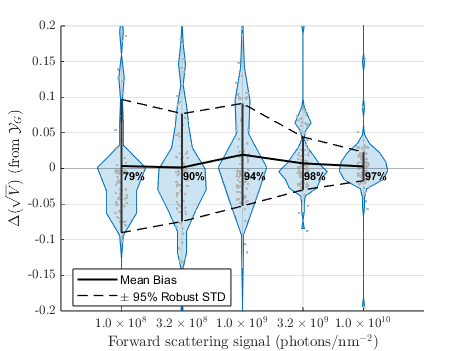


violin_data=violin_data(~arrayfun(@(x) ~x.noise,violin_data)); %remove the groundtruth


% 3. Violin Plot Figure (Toolbox Free)
robust_pct = 95; 
jitter_width = 0.2; % spread of individual points

if v_idx > 0
    figure(7); clf; hold on; grid on;
    num_v = numel(violin_data);
    colors = lines(num_v);
    all_means = nan(1, num_v); all_upper = nan(1, num_v); all_lower = nan(1, num_v);

    for i = 1:num_v
        data = violin_data(i).deltas;
        data(isnan(data) | isinf(data)) = []; 
        if isempty(data), continue; end

        % 1. Manual Percentiles for Robust Stats
        s_data = sort(data);
        N = numel(s_data);
        p_off = (100 - robust_pct) / 2 / 100;
        idx_low = max(1, round(p_off * N));
        idx_high = min(N, round((1 - p_off) * N));
        subset = s_data(idx_low:idx_high);

        % 2. Calculate Stats
        avg = mean(subset); % Using the robust version
        r_std = std(subset); % Using the robust version
        all_means(i) = avg;
        all_upper(i) = avg + r_std;
        all_lower(i) = avg - r_std;

        % 4. Draw Violin Patch
        [counts, centers] = histcounts(data, 35);
        centers = centers(1:end-1) + diff(centers)/2;
        counts = (counts / max(counts)) * 0.4;

        patch([i - counts, fliplr(i + counts)], [centers, fliplr(centers)], colors(1,:), ...
            'FaceAlpha', 0.2, 'EdgeColor', colors(1,:), 'HandleVisibility', 'off');

        % 3. Plot Individual Points (Shaded Jitter) Using random offset
        % within [i - jitter/2, i + jitter/2]
        x_jitter = i + (rand(size(data)) - 0.5) * jitter_width;
        plot(x_jitter, data, '.', 'Color', [0.7 0.7 0.7], 'MarkerSize', 6, 'HandleVisibility', 'off');

        
        % 5. Markers & Text
%         line([i-0.2, i+0.2], [avg, avg], 'Color', colors(1,:),
%         'LineWidth', 2, 'HandleVisibility', 'off');
        % Fixed: changed stdev to r_std to match your robust calculation
        line([i, i], [avg-r_std, avg+r_std], 'Color', [0.2 0.2 0.2], 'LineWidth', 1.5, 'HandleVisibility', 'off');
        
        text(i+jitter_width*1, -0.01, sprintf('%d%%', round(violin_data(i).p_valid)), ...
            'HorizontalAlignment', 'center', 'FontSize', 8, 'FontWeight', 'bold');
    end
    
    % 6. Trend Lines
    plot(1:num_v, all_means, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Mean Bias');
    plot(1:num_v, all_upper, 'k--', 'LineWidth', 1, 'DisplayName', sprintf('\\pm %d%% Robust STD', robust_pct));
    plot(1:num_v, all_lower, 'k--', 'LineWidth', 1, 'HandleVisibility', 'off');
    yline(0, 'k-', 'Alpha', 0.2, 'HandleVisibility', 'off');
    
    % Formatting
% Inside Figure 7 formatting
set(gca, 'TickLabelInterpreter', 'latex'); % Ensure the axis handles LaTeX
set(gca, 'XTick', 1:num_v, 'XTickLabel', ...
    arrayfun(@(x) sprintf('$%s$', latex_noise(x.noise)), violin_data, 'UniformOutput', false));
xlabel('Forward scattering signal (photons/nm$^{-2}$)', 'Interpreter', 'latex');
 ylim(0.2*[-1 1])

    ylabel('$\Delta(\sqrt{V})$ (from $\mathcal{Y}_G$)', 'Interpreter', 'latex'); 
    legend('Location', 'best');

%     title('Discrepancy Distribution with Individual Jitter');
end

% lognormal_spherical_rg4_violin_plot.fig

# create Y_G for noise-less., Spherical formfactor, different distributions

dnames = {'normal','lognormal','schulz','exponential', ...
    'boltzmann','triangular','uniform'};
PSFset=[[3 3];[3 15];[3 25];[25 25];[45 25]];
ndiv=2;
if 1
    % diamond
    SD_dist=360;
    det_side=7/ndiv;
    DETpix=round(1000/ndiv);
    lambda=0.1;
    PSF0=bartlett2d(3,15);
else
    % lab saxs
    SD_dist=150;
    det_side=7/ndiv;
    DETpix=round(1000/ndiv);
    lambda=0.15;
    PSF0=bartlett2d(25,25);
end
rg=4;
use_r3=0;
use_g3=0;

Pxn=[87 85 135 133];
% Pxn=[83 91 103 113]; Pxn=[11 17 3 5];
V_power=.5;
dist_type=dnames{2}; dist_param.N=41;
Vlist=(linspace(0.004^(V_power),0.3^(V_power),20)+0.0000).^(1/V_power);%
% nulist=-0.016;%-1/63;%(-0.016);
nulist=-1/63;%(-0.016);
P_i=2;
PSF0=bartlett2d(PSFset(P_i,1),PSFset(P_i,2));

Dlog=[];
for j=1:numel(nulist)


    %for     NNOIS=0;
    for NNOIS=[ -1/1.6749*10.^([linspace(3,5,5) ]) 0]
        for dist_i=[1:3 5:7]
            for i=1:numel(Vlist)
                if 1
                    [q_mat_x,q_mat_y,I_mat,distrp] = Scatter2D(rg, NNOIS, Vlist(i), nulist(j), DETpix, SD_dist, lambda, det_side, PSF0,dnames{dist_i},dist_param,6);
                else
                    [q_mat_x,q_mat_y,I_mat,distrp] = Scatter2D(rg, NNOIS, Vlist(i), nulist(j), DETpix, SD_dist, lambda, det_side, 1,dnames{dist_i},dist_param,6);
                end                    
                % Compute q-spacing (assume roughly uniform on q_mat_y)
                qvr=hypot(q_mat_y,q_mat_x);
                uqy = unique(q_mat_y(:));
                if numel(uqy) < 2
                    error('q_mat_y grid is degenerate; need at least two unique samples.');
                end
                dq = mean(diff(uqy));
                RG2=rg^2;
                signum=4;

                [~, ~, ~,res] = MG_extract(Pxn, q_mat_x, q_mat_y, I_mat, signum,rg^2,use_r3,use_g3);
                if ~isreal(res.p)
                    disp(';')
                end
                p=res.p;
                g0=p(1);
                g1=p(2);
                g2=p(3);
                m1=p(use_g3+4);
                m2=p(use_g3+5);
                Dlog(end+1).Yg100=g1/g0/g0;
                Dlog(end).dist=dnames{dist_i};
                Dlog(end).nphot=-NNOIS/dq^2;
                Dlog(end).PSF0=PSFset(P_i,:);
                Dlog(end).PSF0c=PSFset(P_i,1)+1i*PSFset(P_i,2);
                Dlog(end).nu=nulist(j);
                Dlog(end).Yg210=g2/g1/g0;
                Dlog(end).Ym210=m2/m1/g0;
                Dlog(end).mean_r=sum(distrp.r.*distrp.p)/sum(distrp.p);
                Dlog(end).V=sum(distrp.r.^2.*distrp.p)/sum(distrp.p)./Dlog(end).mean_r.^2-1;
                Dlog(end).mean_r_wght=sum(distrp.r.^7.*distrp.p)/sum(distrp.r.^6.*distrp.p);
                Dlog(end).V_wght=sum(distrp.r.^6.*distrp.r.^2.*distrp.p)/sum(distrp.r.^6.*distrp.p)./Dlog(end).mean_r_wght.^2-1;
            end
        end
    end
end

Dlog=struct2table(Dlog);
% save Dlog_sphere_mult_dist_r4_quad.mat dq PSF0 dist_param use_r3 use_g3
% Dlog rg Pxn

## plot Y

figure(5)

dist_nam=unique(Dlog.dist); for dist_i=1:numel(dist_nam) ind=find(strcmp(Dlog.dist,dist_nam(dist_i))); % plot(sqrt([Dlog.V(ind)]),[Dlog.Yg100(ind)],'-x',DisplayName=[dist_nam{dist_i}]) plot([Dlog.Yg100(ind)],sqrt([Dlog.V(ind)]),'-x',DisplayName=[dist_nam{dist_i}]) hold on

end ylabel('$\mathcal{Y}_G$',Interpreter='latex') xlabel('\surd V') legend

## Plot Y and Analyze Braid Width

figure(6)
clf;
Dlog_orig=table2struct(Dlog);
noislist=unique(Dlog.nphot);
% for nois_i=1:numel(noislist);
for nois_i=find(~noislist);
Dlog=struct2table(Dlog_orig);
    %     Dlog=Dlog_orig((Dlog_orig.nphot==noislist( nois_i) &
    %     abs(Dlog_orig.mean_r-rg)<0.01),:);
%     Dlog=Dlog((Dlog.nphot==noislist( nois_i) &
%     abs([Dlog.mean_r{:}]'-rg)<0.01),:);
    
Dlog=Dlog((Dlog.nphot==noislist( nois_i) & abs([Dlog.mean_r]-rg)<0.01),:);
%     dist_nam = unique(Dlog.dist);
    dist_nam = dnames;
    hold on;

    % 1. Define a common Y-grid for interpolation We pick the range that is
    % common to all curves to avoid extrapolation errors
    y_min = max(groupsummary(Dlog, 'PSF0c', @(x) min(x), 'Yg100').fun1_Yg100);
    y_max = min(groupsummary(Dlog, 'PSF0c', @(x) max(x), 'Yg100').fun1_Yg100);
    y_grid = linspace(y_min, y_max, 100);
    dist_list=[1:3 5:6];

    % Pre-allocate matrix: rows = y_points, columns = distributions
    x_matrix = zeros(length(y_grid), numel(dist_list));

    % 2. Plot main curves and interpolate
    subplot(3,2,[1 3])
    hold on
    for dist_i = 1:numel(dist_list)
        % Extract indices for this distribution
        ind = strcmp(Dlog.dist, dist_nam(dist_list(dist_i)));

        % Prepare data (sqrt V vs Y)
        curr_x = sqrt(Dlog.V(ind));
        curr_y = Dlog.Yg100(ind);

        % Plot original data
%         plot(curr_x, curr_y, '-', 'DisplayName', sprintf('(%0.0d,%0.0d)
%         pixels',real(dist_nam(dist_i)),imag(dist_nam(dist_i))),
%         'LineWidth', 1.5) plot(curr_x, curr_y, 'x', 'DisplayName',
%         sprintf('%0.2d phot/nm-2',noislist(nois_i)), 'LineWidth', 1.5)
        plot(curr_x, curr_y, 'x-', 'DisplayName', sprintf('%s',string([dist_nam(dist_list(dist_i))])), 'LineWidth', 1.5)

        % Interpolate to find X values at our common Y-grid 'unique'
        % ensures monotonicity for interp1 if data is noisy
        [unique_y, u_idx] = unique(curr_y);
        x_matrix(:, dist_i) = interp1(unique_y, curr_x(u_idx), y_grid, 'linear');
    end

    % 3. Calculate Width (Horizontal Spread)
    braid_width = max(x_matrix, [], 2) - min(x_matrix, [], 2);
    mean_x_pos = mean(x_matrix, 2); % Average X position of the braid

    % 4. Add Visual Aid (Annotation at the 75% mark of the Y range)
    target_idx = round(length(y_grid) * 0.3);
    x_start = min(x_matrix(target_idx, :));
    x_end = max(x_matrix(target_idx, :));
    y_val = y_grid(target_idx);

    line([x_start, x_end], [y_val, y_val], 'Color', 'k', 'LineWidth', 2.5, 'HandleVisibility', 'off');
    text(x_end, y_val, sprintf(' $\\leftarrow \\Delta\\sqrt{V} = %.3f$', braid_width(target_idx)), ...
        'FontWeight', 'bold', 'FontSize', 10,'Interpreter','latex');

    ylabel('$\mathcal{Y}_G$', 'Interpreter', 'latex')
    xlabel('$\sqrt{V}$', 'Interpreter', 'latex')
    h=legend('Location', 'best');
    h.Title.String='Instrument PSF';
    h.Title.String='signal strength';
    h.Title.String='Distribution type';
    grid on
    title('Unweighted')

    % 5. Subplot: Width vs X-position
    subplot(3,2,5)
    plot(mean_x_pos, braid_width, 'k', 'LineWidth', 1.5)
    sbplax1=gca;
    ylabel('Braid width ($\Delta \sqrt{V}$)', 'Interpreter', 'latex')
    xlabel('$\sqrt{V}$', 'Interpreter', 'latex')
%     title('Horizontal Width of Braid vs. Center Position')
    grid on
    disp(noislist(nois_i))
Dlog=struct2table(Dlog_orig);
%     pause
    hold on
end

     0



hold off


## Plot Y and Analyze Braid Width- Weighted

figure(6)
% clf;
Dlog_orig=table2struct(Dlog);
noislist=unique(Dlog.nphot);
% for nois_i=1:numel(noislist);
for nois_i=find(~noislist);
Dlog=struct2table(Dlog_orig);
    %     Dlog=Dlog_orig((Dlog_orig.nphot==noislist( nois_i) &
    %     abs(Dlog_orig.mean_r-rg)<0.01),:);
%     Dlog=Dlog((Dlog.nphot==noislist( nois_i) &
%     abs([Dlog.mean_r{:}]'-rg)<0.01),:);
    
Dlog=Dlog((Dlog.nphot==noislist( nois_i) & abs([Dlog.mean_r]-rg)<0.01),:);
%     dist_nam = unique(Dlog.dist);
    dist_nam = dnames;
    hold on;

    % 1. Define a common Y-grid for interpolation We pick the range that is
    % common to all curves to avoid extrapolation errors
    y_min = max(groupsummary(Dlog, 'PSF0c', @(x) min(x), 'Yg100').fun1_Yg100);
    y_max = min(groupsummary(Dlog, 'PSF0c', @(x) max(x), 'Yg100').fun1_Yg100);
    y_grid = linspace(y_min, y_max, 100);
%     dist_list=[1:3 5:7];

    % Pre-allocate matrix: rows = y_points, columns = distributions
    x_matrix = zeros(length(y_grid), numel(dist_list));

    % 2. Plot main curves and interpolate
    subplot(3,2,[2 4])
    hold on
    for dist_i = 1:numel(dist_list)
        % Extract indices for this distribution
        ind = strcmp(Dlog.dist, dist_nam(dist_list(dist_i)));

        % Prepare data (sqrt V vs Y)
        curr_x = sqrt(Dlog.V_wght(ind));
        curr_y = Dlog.Yg100(ind);

        % Plot original data
%         plot(curr_x, curr_y, '-', 'DisplayName', sprintf('(%0.0d,%0.0d)
%         pixels',real(dist_nam(dist_i)),imag(dist_nam(dist_i))),
%         'LineWidth', 1.5) plot(curr_x, curr_y, 'x', 'DisplayName',
%         sprintf('%0.2d phot/nm-2',noislist(nois_i)), 'LineWidth', 1.5)
        plot(curr_x, curr_y, 'x-', 'DisplayName', sprintf('%s',string([dist_nam(dist_list(dist_i))])), 'LineWidth', 1.5)

        % Interpolate to find X values at our common Y-grid 'unique'
        % ensures monotonicity for interp1 if data is noisy
        [unique_y, u_idx] = unique(curr_y);
        x_matrix(:, dist_i) = interp1(unique_y, curr_x(u_idx), y_grid, 'linear');
    end

    % 3. Calculate Width (Horizontal Spread)
    braid_width = max(x_matrix, [], 2) - min(x_matrix, [], 2);
    mean_x_pos = mean(x_matrix, 2); % Average X position of the braid

    % 4. Add Visual Aid (Annotation at the 75% mark of the Y range)
    target_idx = round(length(y_grid) * 0.3);
    x_start = min(x_matrix(target_idx, :));
    x_end = max(x_matrix(target_idx, :));
    y_val = y_grid(target_idx);

    line([x_start, x_end], [y_val, y_val], 'Color', 'k', 'LineWidth', 2.5, 'HandleVisibility', 'off');
    text(x_end, y_val, sprintf(' $\\leftarrow \\Delta\\sqrt{V} = %.3f$', braid_width(target_idx)), ...
        'FontWeight', 'bold', 'FontSize', 10,'Interpreter','latex');

    ylabel('$\mathcal{Y}_G$', 'Interpreter', 'latex')
    xlabel('Weigthed $\sqrt{V}$', 'Interpreter', 'latex')
    h=legend('Location', 'best');
    h.Title.String='Instrument PSF';
    h.Title.String='signal strength';
    h.Title.String='Distribution type';
    grid on
    title('Scattering weighted')

    % 5. Subplot: Width vs X-position
    subplot(3,2,6)
    plot(mean_x_pos, braid_width, 'k', 'LineWidth', 1.5)
    sbplax2=gca;
    ylabel('Braid width ($\Delta \sqrt{V}$)', 'Interpreter', 'latex')
    xlabel('Weigthed $\sqrt{V}$', 'Interpreter', 'latex')
%     title('Horizontal Width of Braid vs. Center Position')
    grid on
    disp(noislist(nois_i))
Dlog=struct2table(Dlog_orig);
%     pause
    hold on
end

     0



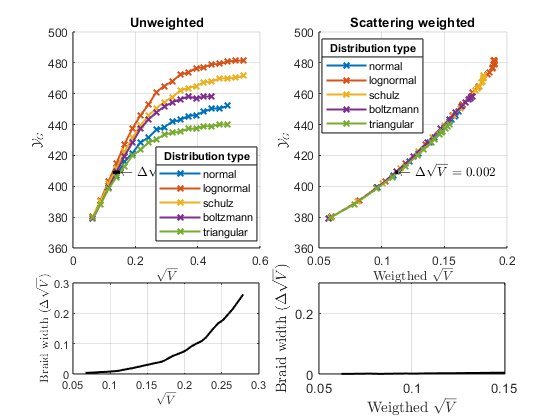

hold off
linkaxes([sbplax1 sbplax2],'y')
h=gca;
h.FontSize=10;

% V_braid_weighted_and_not_spherical_multi_dist_r4.fig

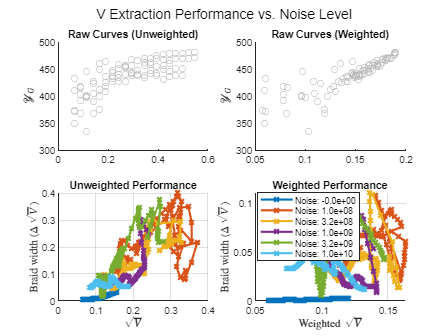

%% Plot Y and Analyze Braid Width Across Noise Levels
figure(7); clf;
Dlog_orig = Dlog; % Work with the table directly
noislist = unique(Dlog_orig.nphot);
dist_nam = dnames;
dist_list = [1:3 5:6]; % Your selected distributions
disp_nois=5;
% Define colors for different noise levels to keep the plot clean
colors = lines(numel(noislist));

for nois_i = 1:numel(noislist)
    % Filter data for current noise level
    curr_noise = noislist(nois_i);
    D_sub = Dlog_orig(Dlog_orig.nphot == curr_noise & abs(Dlog_orig.mean_r - rg) < 0.01, :);
    
    if isempty(D_sub), continue; end

    % --- 1. UNWEIGHTED ANALYSIS ---
    subplot(2,2,[1 ]); hold on;
    % Use strings 'min' and 'max' to ensure predictable column names
    y_min = max(groupsummary(D_sub, 'dist', 'min', 'Yg100').min_Yg100);
    y_max = min(groupsummary(D_sub, 'dist', 'max', 'Yg100').max_Yg100);
    y_grid = linspace(y_min, y_max, 100);
    
    x_matrix_unw = zeros(length(y_grid), numel(dist_list));
    
    for d_idx = 1:numel(dist_list)
        ind = strcmp(D_sub.dist, dist_nam(dist_list(d_idx)));
        if ~any(ind), continue; end
        
        curr_x = sqrt(D_sub.V(ind));
        curr_y = D_sub.Yg100(ind);
        
        % Plotting top: show only the first noise level or a subset to avoid clutter
        if nois_i == disp_nois
            plot(curr_x, curr_y, 'o', 'Color', [0.7 0.7 0.7], 'HandleVisibility', 'off');
        end
        
        [unique_y, u_idx] = unique(curr_y);
        x_matrix_unw(:, d_idx) = interp1(unique_y, curr_x(u_idx), y_grid, 'linear');
    end
    
    % Calculate Braid Width for Unweighted
    bw_unw = max(x_matrix_unw, [], 2) - min(x_matrix_unw, [], 2);
    mean_x_unw = mean(x_matrix_unw, 2);
    
    % Plot Comparison in Subplot 5
    subplot(2,2,3); hold on;
    plot(mean_x_unw, bw_unw, 'x-', 'LineWidth', 2, 'Color', colors(nois_i,:), ...
        'DisplayName', sprintf('Noise: %.1e', curr_noise));

    % --- 2. WEIGHTED ANALYSIS ---
    subplot(2,2,[2 ]); hold on;
    x_matrix_w = zeros(length(y_grid), numel(dist_list));
    
    for d_idx = 1:numel(dist_list)
        ind = strcmp(D_sub.dist, dist_nam(dist_list(d_idx)));
        if ~any(ind), continue; end
        
        curr_x = sqrt(D_sub.V_wght(ind));
        curr_y = D_sub.Yg100(ind);
        
        if nois_i == disp_nois
            plot(curr_x, curr_y, 'o', 'Color', [0.7 0.7 0.7], 'HandleVisibility', 'off');
        end
        
        [unique_y, u_idx] = unique(curr_y);
        x_matrix_w(:, d_idx) = interp1(unique_y, curr_x(u_idx), y_grid, 'linear');
    end
    
    % Calculate Braid Width for Weighted
    bw_w = max(x_matrix_w, [], 2) - min(x_matrix_w, [], 2);
    mean_x_w = mean(x_matrix_w, 2);
    
    % Plot Comparison in Subplot 6
    subplot(2,2,4); hold on;
    plot(mean_x_w, bw_w, 'x-','LineWidth', 2, 'Color', colors(nois_i,:), ...
        'DisplayName', sprintf('Noise: %.1e', curr_noise));
end

% Formatting
subplot(2,2,3); grid on;
ylabel('Braid width ($\Delta \sqrt{V}$)', 'Interpreter', 'latex')
xlabel('$\sqrt{V}$', 'Interpreter', 'latex')
% legend('Location', 'southoutside', 'FontSize', 8);
title('Unweighted Performance');

subplot(2,2,4); grid on;
ylabel('Braid width ($\Delta \sqrt{V}$)', 'Interpreter', 'latex')
xlabel('Weighted $\sqrt{V}$', 'Interpreter', 'latex')
legend('Location', 'best', 'FontSize', 8);
title('Weighted Performance');

subplot(221); title('Raw Curves (Unweighted)'); ylabel('$\mathcal{Y}_G$', 'Interpreter', 'latex');
subplot(222); title('Raw Curves (Weighted)'); ylabel('$\mathcal{Y}_G$', 'Interpreter', 'latex');

sgtitle('V Extraction Performance vs. Noise Level');

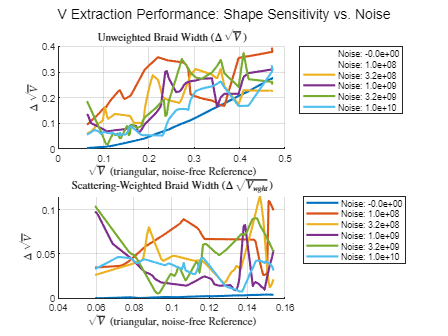

%% Plot Braid Width vs. Log-Normal (or other specific distribution) Noise-Free Variance
figure(9); clf;
Dlog_orig = Dlog; 
noislist = unique(Dlog_orig.nphot);
dist_nam = dnames;
dist_list = [1:3 5:6]; % Distributions to include in the braid
colors = lines(numel(noislist));

% --- 1. ESTABLISH THE LOG-NORMAL NOISE-FREE REFERENCE ---
% Filter for log-normal (dnames{2}) and no noise
spec_dist=6; 
D_ref_log = Dlog_orig(strcmp(Dlog_orig.dist, dnames{spec_dist}) & ...
                      Dlog_orig.nphot == 0 & ...
                      abs(Dlog_orig.mean_r - rg) < 0.01, :);

% Define the Y-grid based on the available range of the reference
[u_y_ref, u_idx] = unique(D_ref_log.Yg100);
y_grid = linspace(min(u_y_ref), max(u_y_ref), 100);

% Map Y_g -> sqrt(V) for the Log-Normal Noise-Free case
ref_V_unw = interp1(u_y_ref, sqrt(D_ref_log.V(u_idx)), y_grid, 'linear', 'extrap');
ref_V_w   = interp1(u_y_ref, sqrt(D_ref_log.V_wght(u_idx)), y_grid, 'linear', 'extrap');


% --- 2. LOOP THROUGH NOISE LEVELS TO CALCULATE BRAID WIDTH ---
for nois_i = 1:numel(noislist)
    curr_noise = noislist(nois_i);
    D_sub = Dlog_orig(Dlog_orig.nphot == curr_noise & abs(Dlog_orig.mean_r - rg) < 0.01, :);
    if isempty(D_sub), continue; end

    % To find the braid width, we need the sqrt(V) of ALL distributions at y_grid
    all_V_unw = zeros(length(y_grid), numel(dist_list));
    all_V_w   = zeros(length(y_grid), numel(dist_list));

    for d_idx = 1:numel(dist_list)
        this_dist_data = D_sub(strcmp(D_sub.dist, dist_nam{dist_list(d_idx)}), :);
        if size(this_dist_data,1) < 2, continue; end
        
        % Interpolate this distribution onto the common Y-grid
        [uy, ui] = unique(this_dist_data.Yg100);
        all_V_unw(:, d_idx) = interp1(uy, sqrt(this_dist_data.V(ui)), y_grid, 'linear', 'extrap');
        all_V_w(:, d_idx)   = interp1(uy, sqrt(this_dist_data.V_wght(ui)), y_grid, 'linear', 'extrap');
    end
    
    % Braid Width = Span across different shapes at the same Y_g
    width_unw = max(all_V_unw, [], 2) - min(all_V_unw, [], 2);
    width_w   = max(all_V_w, [], 2) - min(all_V_w, [], 2);

    % --- 3. PLOT BRAID WIDTH VS. LOG-NORMAL BASELINE ---
    % Unweighted
    subplot(2,1,1); hold on;
    plot(ref_V_unw, width_unw, 'Color', colors(nois_i,:), 'LineWidth', 2, ...
        'DisplayName', sprintf('Noise: %.1e', curr_noise));
    
    % Weighted
    subplot(2,1,2); hold on;
    plot(ref_V_w, width_w, 'Color', colors(nois_i,:), 'LineWidth', 2, ...
        'DisplayName', sprintf('Noise: %.1e', curr_noise));
end

% --- 4. FORMATTING ---
subplot(2,1,1); grid on;
title('Unweighted Braid Width ($\Delta \sqrt{V}$)', 'Interpreter', 'latex');
ylabel('$\Delta \sqrt{V}$', 'Interpreter', 'latex');
xlabel(sprintf('$\\sqrt{V}$ (%s, noise-free Reference)',dnames{spec_dist}), 'Interpreter', 'latex');
legend('Location', 'bestoutside');

subplot(2,1,2); grid on;
title('Scattering-Weighted Braid Width ($\Delta \sqrt{V_{wght}}$)', 'Interpreter', 'latex');
ylabel('$\Delta \sqrt{V}$', 'Interpreter', 'latex');
xlabel(sprintf('$\\sqrt{V}$ (%s, noise-free Reference)',dnames{spec_dist}), 'Interpreter', 'latex');
legend('Location', 'bestoutside');

sgtitle('V Extraction Performance: Shape Sensitivity vs. Noise');

## plot apparent V as a function of p for different distributions

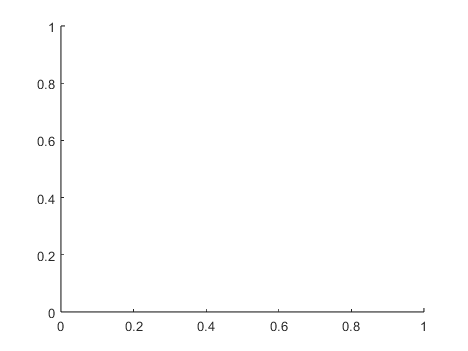

dnames = {'normal','lognormal','schulz','exponential', ...
    'boltzmann','triangular','uniform'};
Dist_sigma=[];
figure(5);clf
for dd=[1 2 3 5 6 7]
    % for dd=[3]
    prange=linspace(0.01,0.9,20);
    for P=prange
        % P=0.5;
        Weight_power=6;
        [r_vect,p] = size_distribution_discrete(400, P.^2, dnames{dd}, [],0,7);
        Er=sum(r_vect.*p)/sum(p);
        Er2=sum(r_vect.^2.*p)/sum(p);
        Sigm=sqrt(Er2-Er^2);
        Erw=sum(r_vect.*p.*r_vect.^Weight_power)/sum(p.*r_vect.^Weight_power);
        Er2w=sum(r_vect.^2.*p.*r_vect.^Weight_power)/sum(p.*r_vect.^Weight_power);
        Sigmw=sqrt(Er2w-Erw^2);
        Dist_sigma(end+1).dist_type=dnames{dd};
        Dist_sigma(end).Sigm=Sigm;
        Dist_sigma(end).Er=Er;
        Dist_sigma(end).Sigmw=Sigmw;
        Dist_sigma(end).Erw=Erw;
        Dist_sigma(end).p=P;
        figure (5);
%         plot(r_vect,p,'-',[Er Er+Sigm],max(p)*[1.1 1.1],'x-',[Erw
%         Erw+Sigmw],max(p)/2*[1 1],'d-')
        hold on

    end
end

Dit=struct2table(Dist_sigma);
if size(Dit,1)==1
    types={Dit.dist_type};
else
    types=unique(Dit.dist_type);
end
figure(1)
clf
hold on
SiwvsSip=[];
for i=1:numel(types)
    Di_si=(Dit(strcmp(Dit.dist_type,types{i}),:));
    subplot(311)
    SiwvsSip(i,:)=polyfit(Di_si.Sigm./Di_si.Er,Di_si.Sigmw./Di_si.Erw,3);
    plot(Di_si.Sigm./Di_si.Er,Di_si.Sigmw./Di_si.Erw,'x-','DisplayName',types{i});title('sigmaw vs sigma')
    % plot(Di_si.p,(Di_si.Sigmw./Di_si.Erw)./Di_si.Sigm./Di_si.Er,'x-','DisplayName',types{i});title('sigmaw/sigma
    % vs p')
    hold on
    
%     plot(prange,polyval(SiwvsSip(i,:),prange)); axis equal
    subplot(312)
    plot(Di_si.Er,Di_si.Erw,'x-','DisplayName',types{i});title('E(r)w vs E(r)')
    hold on
end

legend('Location','best')
% subplot(313) %
%  P=linspace(min(Dit.Sigm),max(Dit.Sigm),10);
% %
SiwtoSi=[];
for i=1:numel(P)
    %     temp=find(Dit.p==P(i));
    %     SiwtoSi(i)=max(abs(Dit(temp,:).Sigmw-Dit(temp,:).Sigm)); pii(i)=
    rng=[0,inf];
    for j=1:size(SiwvsSip,1)
        temp=polyval(SiwvsSip(j,:),P(i));
        if temp>rng(1)
            rng(1)=temp;
        end
        if temp<rng(2)
            rng(2)=temp;
        end
         
    end
    SiwtoSi(i,:)=rng;
end
plot(P,P.*abs(diff(SiwtoSi')))


%
% Deduce span of true std (sigma) compatible with a given weighted std
% (sigma_w)

% Normalized sigmas
Dit.sigma  = Dit.Sigm  ./ Dit.Er;
Dit.sigmaw = Dit.Sigmw ./ Dit.Erw;

types = unique(Dit.dist_type);

% Build interpolants sigma_w = f_dist(sigma), handling duplicates
F = struct();
for i = 1:numel(types)
    idx = strcmp(Dit.dist_type, types{i});
    si  = Dit.sigma(idx);
    siw = Dit.sigmaw(idx);

    % Sort
    [si, ord] = sort(si);
    siw = siw(ord);

    % --- REMOVE DUPLICATES IN sigma ---
    [si_u, ~, ic] = unique(si, 'stable');
    siw_u = accumarray(ic, siw, [], @mean);

    % Store interpolant
    F(i).type = types{i};
    F(i).fwd  = griddedInterpolant(si_u, siw_u, 'pchip', 'none');
end

Error using griddedInterpolant
The sample points must be finite.

% Define sigma_w grid (observable)
sigmaw_grid = linspace( ...
    min(Dit.sigmaw), ...
    max(Dit.sigmaw), ...
    50 );

sigma_span = nan(numel(sigmaw_grid), 2);

% Invert interpolants numerically
for k = 1:numel(sigmaw_grid)
    sw = sigmaw_grid(k);

    sigmas = [];

    for i = 1:numel(F)
        % Sample sigma domain of this distribution
        si = F(i).fwd.GridVectors{1};
        siw = F(i).fwd.Values;

        % Look for crossings of sigma_w = sw
        d = siw - sw;
        idx = find(d(1:end-1).*d(2:end) <= 0);  % sign change

        for j = idx'
            % Linear interpolation for inverse
            sig = interp1(siw(j:j+1), si(j:j+1), sw, 'linear');
            if ~isnan(sig)
                sigmas(end+1) = sig; %#ok<SAGROW>
            end
        end
    end

    if ~isempty(sigmas)
        sigma_span(k,:) = [min(sigmas), max(sigmas)];
    end
end

% Plot span vs unweighted sigma
figure (3); clf
hold on
plot(sigmaw_grid, sigma_span(:,1), 'k--', 'LineWidth', 1.5)
plot(sigmaw_grid, sigma_span(:,2), 'k--', 'LineWidth', 1.5)
fill([sigmaw_grid fliplr(sigmaw_grid)], ...
     [sigma_span(:,1)' fliplr(sigma_span(:,2)')], ...
     [0.7 0.7 0.7], 'FaceAlpha', 0.4, 'EdgeColor', 'none')

xlabel('\sigma_w (weighted, observable)')
ylabel('\sigma (true, unweighted)')
title('Deduction span of true \sigma given \sigma_w')
grid on
% Plot span vs unweighted sigma figure (1); subplot (313) % hold on
% plot(sigmaw_grid, abs(sigma_span(:,1)-sigma_span(:,2)), 'k--',
% 'LineWidth', 1.5)
% 
% 
% xlabel('\sigma_w (weighted, observable)') ylabel('\sigma (true,
% unweighted)') title('Deduction span of true \sigma given \sigma_w') grid
% on
%
figure(1); subplot(313); 

% Average true sigma corresponding to observed sigma_w
sigma_avg = mean(sigma_span, 2);

% Deduction span
sigma_span_width = abs(sigma_span(:,2) - sigma_span(:,1));

plot(sigma_avg, sigma_span_width, 'k-', 'LineWidth', 1.5)

xlabel('{\sigma}_{avg} (true, inferred)')
ylabel('\Delta\sigma (deduced span)')
title('Uncertainty span of true \sigma inferred from weighted \sigma_w')
grid on

## SAXS Analysis: Radius of Gyration Distribution for a Broken Rod

Version: Standard MATLAB (No Toolboxes Required) This script simulates the distribution of Rg/L for an isotropically hinged rod as a function of the hinge position 's'.

clear; clc; close all;

% Parameters
L = 1;                  % Total length
s_values = 0.01:0.04:0.5;  % Hinge positions (spaced for visual clarity)
num_samples = 200000;    % Samples per s-value for the distribution
num_bins = 40;          % Bins for the distribution width

% Preallocate for the mean line
Rg_mean_sq = zeros(size(s_values));

% Setup Figure
figure('Color', 'w', 'Position', [100, 100, 900, 600]);
hold on;

% 1. Calculation and Plotting Loop
for i = 1:length(s_values)
    s = s_values(i);
    
    % Analytical Mean Squared Rg (from Eq. 34)
    Rg_mean_sq(i) = (L^2 / 12) * (1 - 6*s^2 * (1-s)^2);
    
    % --- Distribution Simulation --- Isotropic hinge: cos(alpha) is
    % uniform between -1 and 1
    cos_alpha = 2 * rand(1, num_samples) - 1;
%     cos_alpha = cos(rand(1, num_samples)*pi);
    
    % Constants for Eq. 31 (Radius of Gyration for a fixed angle)
    term1 = s^3 + (1-s)^3;
    term2 = s^4 + (1-s)^4;
    term3 = 2 * s^2 * (1-s)^2;
    
    % Instantaneous Rg/L (Eq. 31)
    Rg_sq_inst = (L^2/3)*term1 - (L^2/4)*(term2 + term3*cos_alpha);
    Rg_inst = sqrt(Rg_sq_inst) / L;
    
    % --- Manual Density Estimation (Replacing ksdensity) ---
    [counts, centers] = hist(Rg_inst, num_bins);
    
    % Normalize and scale for horizontal width in the plot Width of the
    % mandoline 'body' is proportional to probability density
    density = (counts / max(counts)) * 0.015; 
    
    % Create the "Mandoline" shape by mirroring the histogram We use 'fill'
    % to create a smooth-looking polygon
    x_coords = [s - density, flip(s + density)];
    y_coords = [centers, flip(centers)];
    
    % Color gradient: shift from blue to purple as s increases
    color_val = [0.2, 0.4, 0.8] * (1-s) + [0.5, 0.1, 0.5] * s;
    
    fill(x_coords, y_coords, color_val, ...
        'FaceAlpha', 0.4, 'EdgeColor', color_val, 'LineWidth', 0.5);
end

% 2. Plot the Analytical Mean (The "Strings" of the Mandoline)
plot(s_values, sqrt(Rg_mean_sq)/L, 'r', 'LineWidth', 2.5);

% 3. Plot theoretical limits (The "Bridge" of the Mandoline) Max Rg occurs
% at cos(alpha) = -1 (extended), Min at cos(alpha) = 1 (folded)
s_fine = 0:0.005:0.5;
max_Rg = sqrt((L^2/3)*(s_fine.^3 + (1-s_fine).^3) - (L^2/4)*(s_fine.^4 + (1-s_fine).^4 - 2*s_fine.^2.*(1-s_fine).^2)) / L;
min_Rg = sqrt((L^2/3)*(s_fine.^3 + (1-s_fine).^3) - (L^2/4)*(s_fine.^4 + (1-s_fine).^4 + 2*s_fine.^2.*(1-s_fine).^2)) / L;

plot(s_fine, max_Rg, 'k--', 'LineWidth', 1);
plot(s_fine, min_Rg, 'k--', 'LineWidth', 1);

% Formatting
xlabel('Hinge Position (s)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Radius of Gyration (R_g / L)', 'FontSize', 12, 'FontWeight', 'bold');
title({'Violin Plot: R_g Distribution of an Isotropically Hinged Rod', ...
       'Analytical Mean vs. Configurational Ensemble'}, 'FontSize', 14);
grid on;
set(gca, 'Box', 'on', 'TickDir', 'out', 'LineWidth', 1.2);
legend('Configurational Probability Density', 'Analytical Mean \langleR_g\rangle', ...
       'Theoretical Limits (Ext/Fold)', 'Location', 'southwest');

% Set axes to show the narrowing distribution at s=0
ylim([0.1 0.35]);
xlim([-0.05 0.55]);

fprintf('Calculation Complete. Standard MATLAB logic applied.\n');